# Removing Unevenly Bright Background in an Image

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

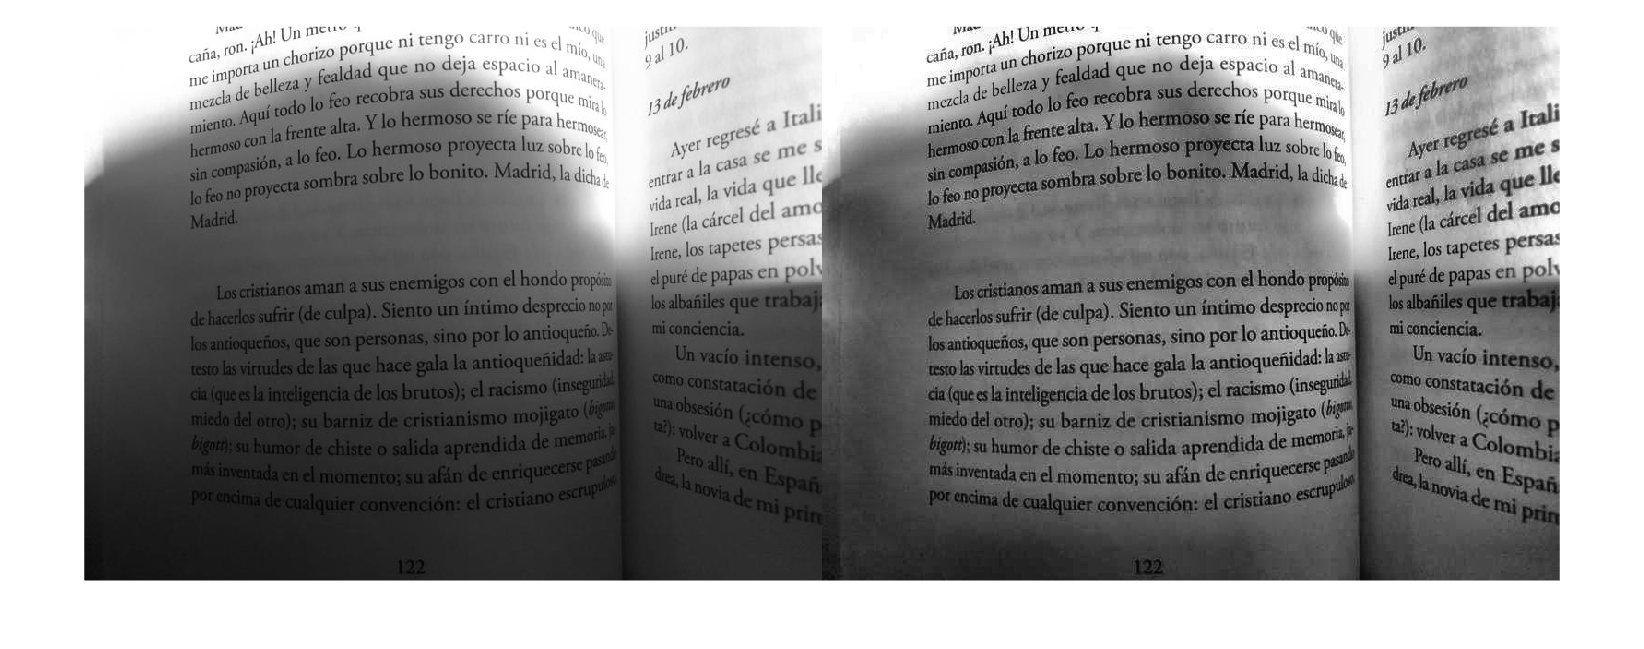

book = imread("./images/book.jpg");
book = im2gray(book);
bookAdapt = adapthisteq(book);
imshowpair(book, bookAdapt, "montage")

## Task 1

When the background is bright, you need to even out variation in bright intensities. Use `imbothat` to subtract the image from its bright background.  

`im2` `=` `imbothat``(``im``, nhood``)``;`

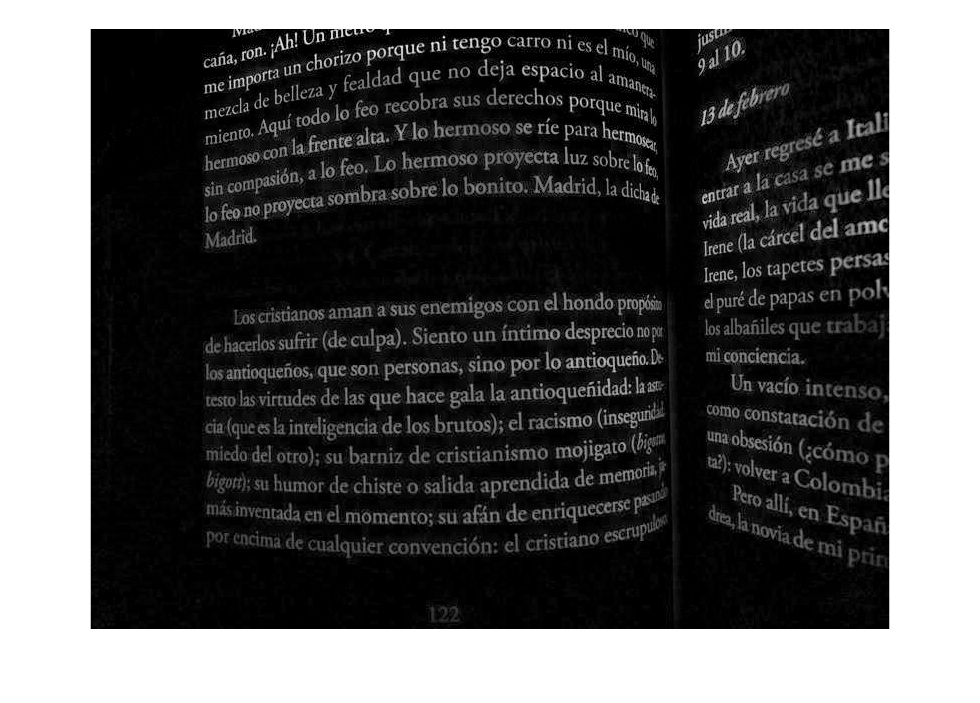

nhood = ones(10);
bookBotHat = imbothat(bookAdapt, nhood);
imshow(bookBotHat)

## Task 2

You can use `imcomplement` to invert a grayscale image.

`imC` `=` `imcomplement``(``im``)``;`

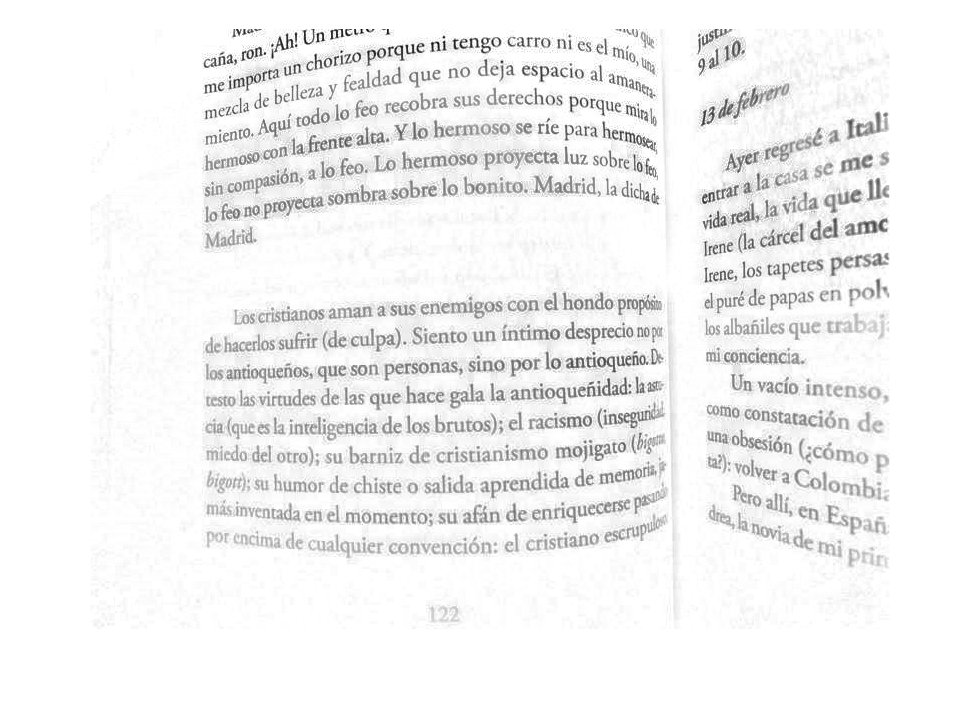

bookBotHat = imcomplement(bookBotHat);
imshow(bookBotHat)